# Parameters

clear
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122


k = 400

k = 400

%periodo = 3.7837



## Unstable Manifold L1

X0 = [0.817717447531650 0 0 0.187660123872420]

X0 =     0.8177         0         0    0.1877


C1 = jacobiConstant([0.817717447531650 0],[0 0.187660123872420],mu)

C1 = 3.1630

STM = reshape(eye(4),16,[])';
Xunstable = [X0 STM]';
epsilon=1e-4;
periodoUnstable = 2.81367408421178;
X_mainfold_unstable = calculateUnStableMainfold(periodoUnstable,Xunstable,mu,k,epsilon,1,false);


## stable manifold L2

X0 = [1.17818035065113 0 0 -0.136466046934286];
C1 = jacobiConstant([1.17818035065113 0],[0 -0.136466046934286],mu)

C1 = 3.1630

STM = reshape(eye(4),16,[])';
Xstable = [X0 STM]';
periodoStable = 3.40447304395081;
X_mainfold_stable = calculateStableMainfold(periodoUnstable,Xstable,mu,k,epsilon,-1,false);


## Verificar orbitas

hold on
plotStableMainfold(X_mainfold_stable,periodoStable,k,mu,'r')

plotUnStableMainfold(X_mainfold_unstable,periodoUnstable,k,mu,'b')

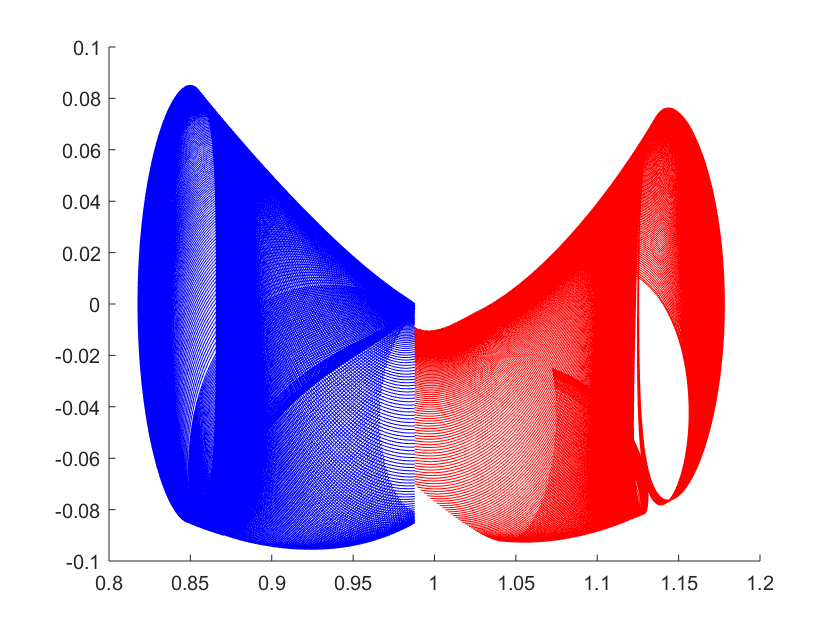

hold off

## Calculate Poincare map

ans =    369     3


ans =      1     3


ans =    401     3


ans =      1     3


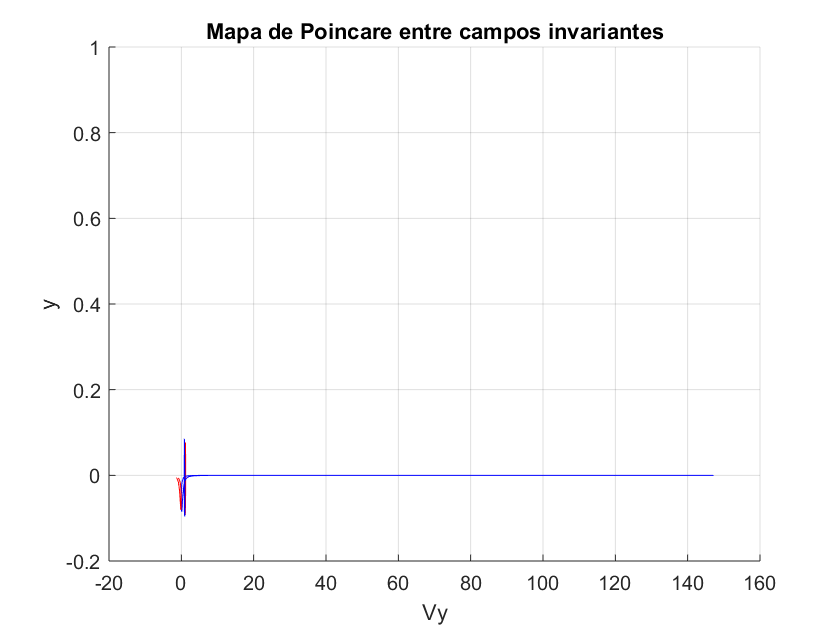

unstable_size =    368     1


stable_size =    368     1


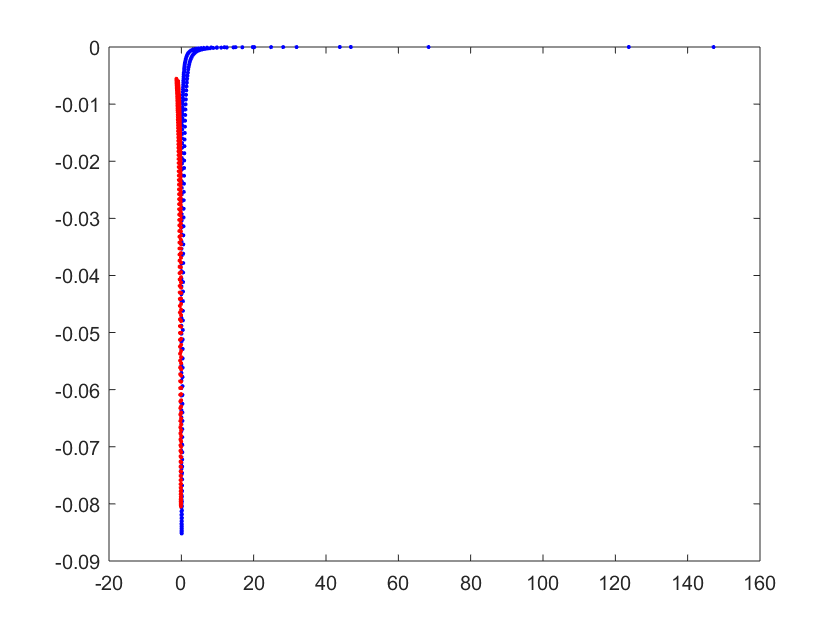


[U2,U3] = callPoincareMap(X_mainfold_unstable,X_mainfold_stable,mu,k,C1,periodoStable*3,periodoStable*3);